# Simulación de Sistemas Eléctricos

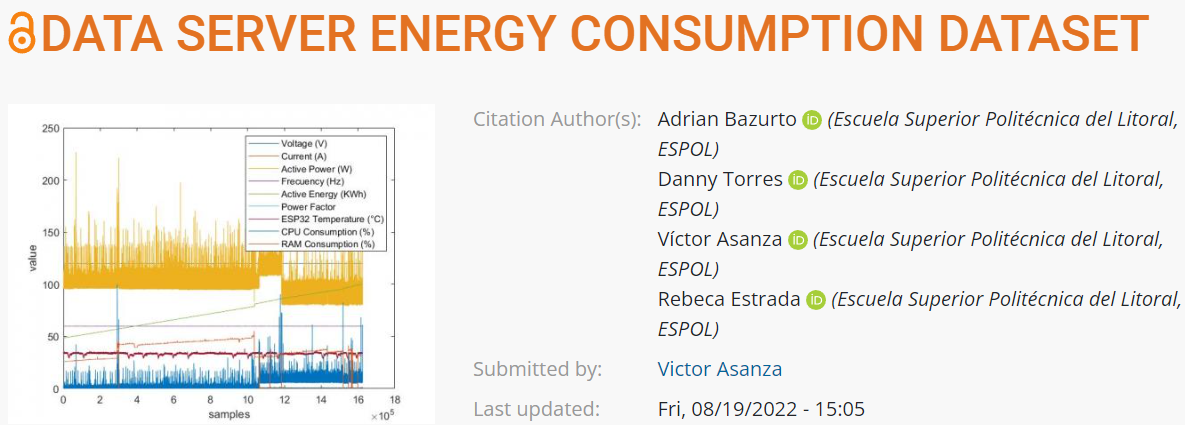

# Actividad 4: Load CSV file

**Simulación de Sistemas Eléctricos**

Nombres:

- Estudiante 1: VA

- Estudiante 2: VA

Contenido:

- Descargar datos (.csv) desde desde repositorio (DataPort)

- **Paper: **[https://doi.org/10.1016/j.procs.2022.07.035](https://doi.org/10.1016/j.procs.2022.07.035)

- **Dataset:** [https://ieee-dataport.org/open-access/data-server-energy-consumption-dataset](https://ieee-dataport.org/open-access/data-server-energy-consumption-dataset)

- **Codigo Matlab:** [https://github.com/vasanza/EnergyConsumptionPrediction](https://github.com/vasanza/EnergyConsumptionPrediction)

- Almacenar el archivo dataset.m en la carpeta ./data

- **1.- Leer el archivo usando Matlab y graficar los datos**

- **2.- Normalizar los datos usando la funcion fNormalization**

- [https://github.com/vasanza/Matlab_Code](https://github.com/vasanza/Matlab_Code)

- **Nota:** realizar cualquier cambio que usted considere adecuado

#### **1.- Eliminar datos de memoria y command window**

clear; %Borrar el korspace
clc; %Borrar el command window

#### 2.- Configuración de carpeta /src para librerias

%nombre de la carpeta donde estan los codigos
addpath(genpath('./src'));

**3- Configuranción de carpeta de /data para datasets**

%Nombre de la carpeta donde estan los archvios csv
datapath=fullfile('./data/');
filenames=FindCSV(datapath);

#### 4- Cargar dataset desde carpeta data

%Esto es lo que se hace con datos .mat
% path=fullfile('./data/dataset.mat');
% data=load(path); %Retorna como resultado una estructura
% data=data.data; %Accedemos a la tabla que se contiene dentro de la estructura
% dataArray=table2array(data(:,4:12));%Convertimos la tabla en arreglo

%Esto es lo que se hace con datos .csv
data=readtable(fullfile(datapath,filenames(1).name));
%clear dataRaw; %Borrar de memoria la variable que no usare despues
%Seleccionar las variables electricas de interes
data2=table2array(data(:,1:6)); % Convertir datos de string a float o int
data2(isnan(data2))=0; % Eliminar los datos NaN

**5.- Guardar los archivos en .MAT**

save(fullfile(datapath,'datset.mat'),'data2');

#### 6.- Graficar todas las Variables

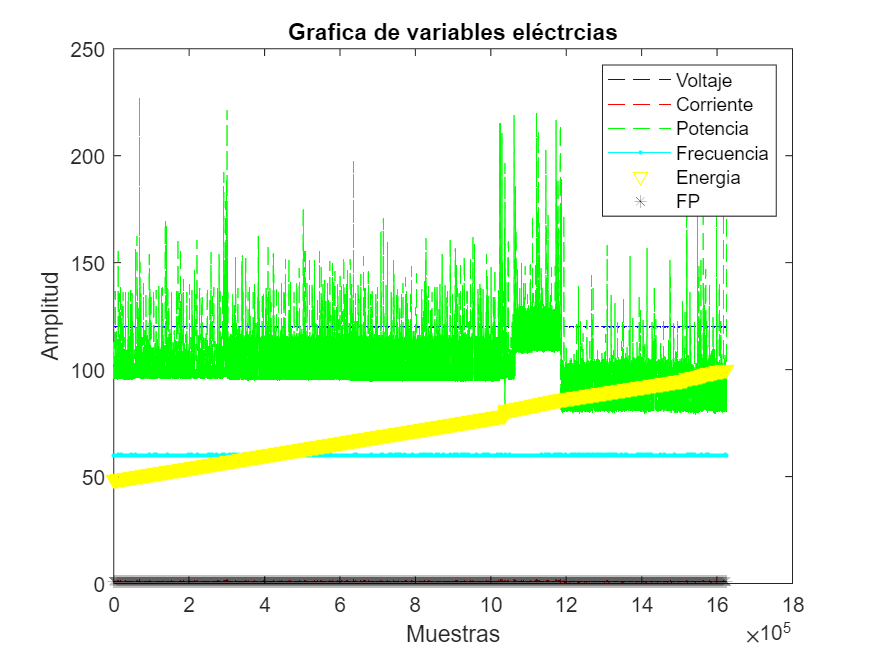

Voltaje=data2(:,1);
Corriente=data2(:,2);
Potencia=data2(:,3);
Frecuencia=data2(:,4);
Energia=data2(:,5);
FP=data2(:,6);

figure %crear una nueva grafica
%plot(data2) %plotea la grafica 1
plot(Voltaje,'b--',LineWidth=0.1);
hold on %habilita plotear mas de una grafica en la misma figura
plot(Corriente,'r--',LineWidth=0.1);
plot(Potencia,'g--',LineWidth=0.1);
plot(Frecuencia,'c.-',LineWidth=0.1);
plot(Energia,'yv',LineWidth=0.5);
plot(FP,'k*',LineWidth=0.1);
hold off

title('Grafica de variables eléctrcias');
xlabel('Muestras');
ylabel('Amplitud');
legend('Voltaje','Corriente','Potencia','Frecuencia','Energia','FP');

**7.- Grafica de datos normalizados**

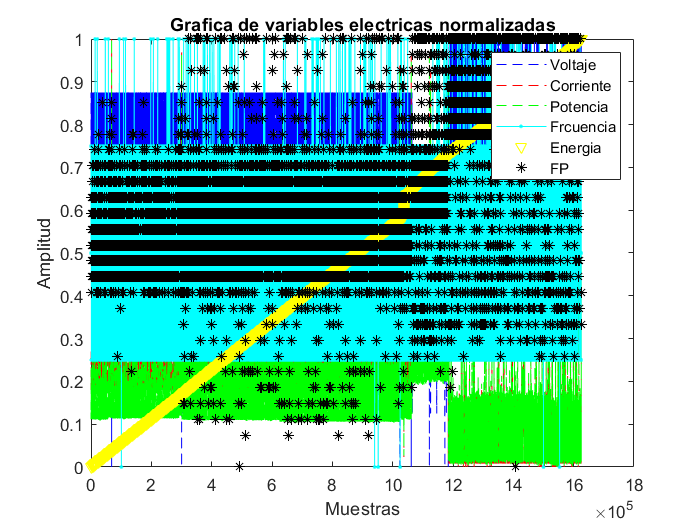

[dataArrayNorm] = fNormalization(data2);

VoltajeNorm=dataArrayNorm(:,1);
CorrienteNorm=dataArrayNorm(:,2);
PotenciaNorm=dataArrayNorm(:,3);
FrecuenciaNorm=dataArrayNorm(:,4);
EnergiaNorm=dataArrayNorm(:,5);
FPNorm=dataArrayNorm(:,6);

figure %crear una nueva grafica
plot(VoltajeNorm,'b--',LineWidth=0.1);
hold on %habilita plotear mas de una grafica en la misma figura
plot(CorrienteNorm,'r--',LineWidth=0.1);
plot(PotenciaNorm,'g--',LineWidth=0.1);
plot(FrecuenciaNorm,'c.-',LineWidth=0.1);
plot(EnergiaNorm,'yv',LineWidth=0.5);
plot(FPNorm,'k*',LineWidth=0.1);
hold off

title('Grafica de variables electricas normalizadas');
xlabel('Muestras');
ylabel('Amplitud');
legend('Voltaje','Corriente','Potencia','Frcuencia','Energia','FP');